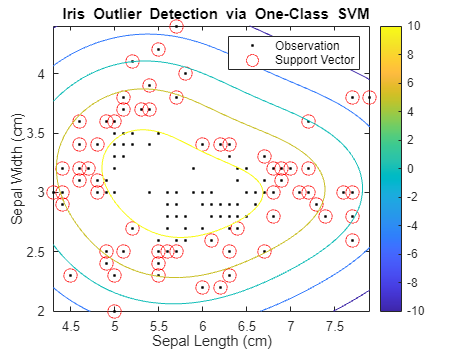

% 使用 SVM 和一类学习检测离群值
% 通过将所有鸢尾花分配给同一个类来修改 Fisher 的鸢尾花数据集。
% 检测修改后的数据集中的离群值，并确认观测值中离群值的预期比例。

% 加载 Fisher 鸢尾花数据集。删除花瓣的长度和宽度。
% 将所有鸢尾花都视为来自同一个类。

load fisheriris
X = meas(:,1:2);
y = ones(size(X,1),1);
% 使用修改后的数据集训练 SVM 分类器。假设 5% 的观测值是离群值。对预测变量进行标准化。

rng(1);
SVMModel = fitcsvm(X,y,'KernelScale','auto','Standardize',true,...
    'OutlierFraction',0.05);
% SVMModel 是经过训练的 ClassificationSVM 分类器。
% 默认情况下，软件使用高斯核进行一类学习。
% 绘制观测值和决策边界。标记支持向量和潜在离群值。

svInd = SVMModel.IsSupportVector;
h = 0.02; % Mesh grid step size
[X1,X2] = meshgrid(min(X(:,1)):h:max(X(:,1)),...
    min(X(:,2)):h:max(X(:,2)));
[~,score] = predict(SVMModel,[X1(:),X2(:)]);
scoreGrid = reshape(score,size(X1,1),size(X2,2));

figure
plot(X(:,1),X(:,2),'k.')
hold on
plot(X(svInd,1),X(svInd,2),'ro','MarkerSize',10)
contour(X1,X2,scoreGrid)
colorbar;
title('{\bf Iris Outlier Detection via One-Class SVM}')
xlabel('Sepal Length (cm)')
ylabel('Sepal Width (cm)')
legend('Observation','Support Vector')
hold off


% 将离群值与其余数据分隔的边界出现在围道值为 0 的位置。

% 验证交叉验证数据中具有负分数的观测值的比例接近 5%。

CVSVMModel = crossval(SVMModel);
[~,scorePred] = kfoldPredict(CVSVMModel);
outlierRate = mean(scorePred<0)

outlierRate = 0.0467

% outlierRate = 0.0467